cutoff_fourier = [29    21    19    16];%[19    16];%
cutoff_spectral = [78, 26, 19, 13];%[19, 13];% 
nu = [0.5, 1.5, 2.5 0];%[2.5 0];%
titles = {'0.5','1.5','2.5', 'infinity'};%{'2.5', 'infinity'};%
c_alpha = 3;

5.1:

Richardson Extrapolation

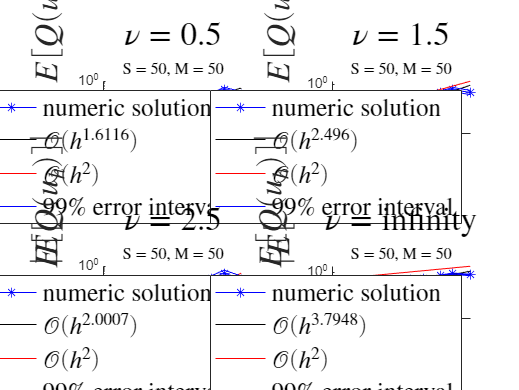

I = [2^2,6,2^3,12,2^4,24,28,2^5,36,40,50,2^6];
h = 1./I;
M = [50,50,50,50];
S = [50,50,50,50];

QMC_diff = zeros(length(nu),length(I));

figure

for j = 1:length(nu)
    error = zeros(1,length(I));
    y = i4_sobol_generate(cutoff_fourier(1),M(j),0);
    z = i4_sobol_generate(cutoff_fourier(1),M(j),0);
    Shift_y = cell(1,S(j));
    Shift_z = cell(1,S(j));
    for s = 1:S(j)
        Shift_y{s} = rand(cutoff_fourier(1),M(j));
        Shift_z{s} = rand(cutoff_fourier(1),M(j));
    end
    fourier = fourierkoeff(nu(j),cutoff_fourier(j));
    %[EWsort,EVsort] = eigC(2*I(length(I)),h(length(I))/2,nu(j));
    for i = 1:length(I)
        V1 = zeros(1,S(j));
        V2 = zeros(1,S(j));
        for s = 1:S(j)
            y_shifted = applyShift(y,Shift_y{s});
            z_shifted = applyShift(z,Shift_z{s});
            for m = 1:M(j)
                V1(s) = V1(s) + CalculateQoIa2_3( I(i), h(i),fourier,cutoff_fourier(j),y_shifted(:,m),z_shifted(:,m));
                V2(s) = V2(s) + CalculateQoIa2_3( 2*I(i), h(i)/2,fourier,cutoff_fourier(j),y_shifted(:,m),z_shifted(:,m));
                %V1(s) = V1(s) + CalculateQoI( I(i), h(i),y_shifted(:,m),cutoff_spectral(j),EWsort,EVsort);
                %V2(s) = V2(s) + CalculateQoI( 2*I(i), h(i)/2,y_shifted(:,m),cutoff_spectral(j),EWsort,EVsort);
            end 
            QMC_diff(j,i) = QMC_diff(j,i) + V1(s) - V2(s);
            V1=V1/M(j);
            V2=V2/M(j);
        end
        QMC_diff(j,i) = abs(QMC_diff(j,i))/(M(j)*S(j));
        Var = 0;
        for s = 1:S(j)
            Var = Var + ( V1(s)-V2(s) - QMC_diff(j,i) )^2;
        end
        Var = Var/(S(j)-1);
        error(i) = sqrt(Var)*c_alpha/(sqrt(S(j)));
    end
    upperbound = QMC_diff(j,:) + error;
    factor = upperbound ./ QMC_diff(j,:);
    lowerbound = QMC_diff(j,:)./factor;
    deg = polyfit(log(h),log(QMC_diff(j,:)),1);
    subplot(2,2,j)
    hold on

    plot(h, QMC_diff(j,:),'*-b')
    plot(h, h.^deg(1).*exp(deg(2)), 'k')
    plot(h, h.^2.*exp(deg(2)), 'r')
    plot(h,upperbound,'-b')
    plot(h,lowerbound,'-b')

    hold off
    set(gca, 'XScale', 'log', 'YScale', 'log')
    legend('numeric solution',['$\mathcal{O}(h^{',num2str(deg(1)),'})$'],'$\mathcal{O}(h^{2})$','99\% error interval','interpreter','latex','FontSize',15','Location','southeast')
    title(['$\nu = $' , titles{j}],['S = ', num2str(S(j)), ', M = ', num2str(M(j))],'FontSize',15,'interpreter','latex','FontSize',20)
    xlabel('$h$','FontSize',20,'interpreter','latex')
    ylabel('$| E[Q(u_{2h})] - E[Q(u_{h})]|$','FontSize',20,'interpreter','latex')
end

Adaptive MC

M0 = 5;
S0 = 80;
p=[2,2,2,2];

TOL=0.1;
I0=4;
h0=1/I0;

h_MC = zeros(1,length(nu));

for j = 1:length(nu)

    [stepsize,samples,MCRes,StatisticalEr,BiasEr,RE,Variance_level,rt] = AdaptiveMC(M0,S0, p(j), c_alpha, TOL, I0, h0, nu(j),cutoff_fourier(j))

    h_MC(j) = stepsize(length(stepsize))
    deg = polyfit(log(samples),log(StatisticalEr),1);
    figure;
    subplot(2,2,1)
    plot(stepsize, BiasEr,'*--b')
    set(gca, 'YScale', 'log', 'XScale', 'log')
    xlabel('h','interpreter','latex','FontSize',20)
    title('Relative Bias Error',['$\nu = $' , titles{j}],'FontSize',20,'interpreter','latex')
    
    subplot(2,2,2)
    hold on
    plot(samples, StatisticalEr,'*--b')
    plot(samples, samples.^deg(1).*exp(deg(2)),'r')
    set(gca, 'YScale', 'log', 'XScale', 'log')
    xlabel('S','FontSize',20)
    legend('CLT bound',['$\mathcal{O}(S^{',num2str(deg(1)),'})$'],'interpreter','latex','FontSize',20)
    title('Relative Statistical Error',['$\nu = $' , titles{j}],'FontSize',20,'interpreter','latex')
    hold off


    subplot(2,2,3)
    plot(linspace(1,rt-1,rt-1), RE(1,1:rt-1),'*--b')
    set(gca, 'YScale', 'log')
    xlabel('Number of Iterations','FontSize',20)
    title('Relative Error',['$\nu = $' , titles{j}],'FontSize',20,'interpreter','latex')  
    
    subplot(2,2,4)
    plot(linspace(1,rt-1,rt-1), MCRes(2,1:rt-1),'*--b')
    set(gca, 'YScale', 'log')
    xlabel('Number of Iterations','FontSize',20)
    title('MC Result',['$\nu = $' , titles{j}],'FontSize',20,'interpreter','latex')

end

Bias = 0.0883

stat = 0.2491

Bias = 0.0992

stat = 0.1555

Bias = 0.0090

stat = 0.1202

5.2:

Estimating cost and Variance:

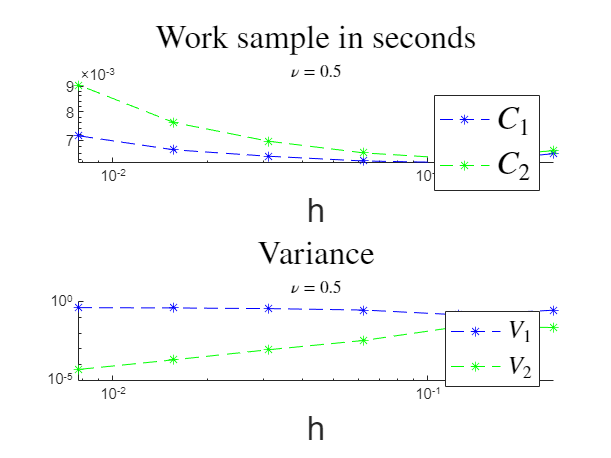

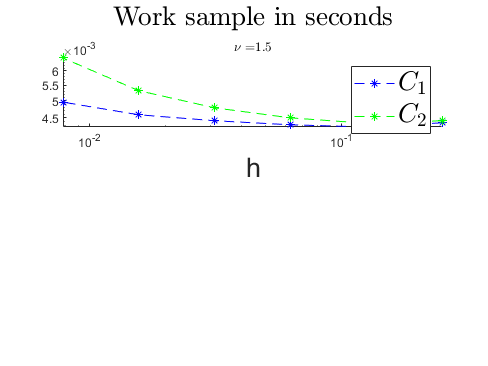

Arrays have incompatible sizes for this operation.

Error in HW2_exercise2>applyShift (line 494)
    R = R + S;

Related documentation

I = [2^2,2^3,2^4,2^5,2^6,2^7];
h = 1./I;
M = [10,10,10,10];
S = [500,500,500,500];
N = 100;
Var_1 = zeros(length(nu),length(I));
Var_2 = zeros(length(nu),length(I));

for j = 1:length(nu)
    C_1 = zeros(N,length(I));
    C_2 = zeros(N,length(I));
    for n = 1:N
        for i = 1:length(I)
            tC1 = tic;
            y = i4_sobol_generate(cutoff_fourier(1),1,0);
            z = i4_sobol_generate(cutoff_fourier(1),1,0);
            y_shifted = applyShift(y,rand(cutoff_fourier(1),1));
            z_shifted = applyShift(z,rand(cutoff_fourier(1),1));
            fourier = fourierkoeff(nu(j),cutoff_fourier(j));
            CalculateQoIa2_3( I(i), h(i),fourier,cutoff_fourier(j),y_shifted,z_shifted);
            C_1(n,i) = toc(tC1);

            tC2 = tic;
            CalculateQoIa2_3( 2*I(i), h(i)/2,fourier,cutoff_fourier(j),y_shifted,z_shifted);
            C_2(n,i) = toc(tC2) + C_1(n,i);
        end
    end
    figure
    subplot(2,1,1)
    hold on
    set(gca, 'XScale', 'log', 'YScale', 'log')
    plot(h,mean(C_1),'*--b')
    plot(h,mean(C_2),'*--g')
    hold off

    title('Work sample in seconds',['$\nu = $' , titles{j}],'FontSize',20,'interpreter','latex')
    xlabel('h','FontSize',20)
    legend('$C_1$','$C_2$','interpreter','latex','FontSize',20)


    MCRes=zeros(2,length(I));
    QDiff=zeros(1,length(I));

    y = i4_sobol_generate(cutoff_fourier(1),M(j),0);
    z = i4_sobol_generate(cutoff_fourier(1),M(j),0);
    hift_y = cell(1,S(j));
    Shift_z = cell(1,S(j));
    for s = 1:S(j)
        Shift_y{s} = rand(cutoff_fourier(1),M(j));
        Shift_z{s} = rand(cutoff_fourier(1),M(j));
    end
    y_shifted = applyShift(y,Shift_y{s});
    z_shifted = applyShift(z,Shift_z{s});
    for i = 1:length(I)
        V1 = zeros(1,S(j));
        V2 = zeros(1,S(j));
        for s = 1:S(j)
            for m=1:M(j)
                V1(s) = V1(s) + CalculateQoIa2_3( I(i), h(i),fourier,cutoff_fourier(j),y(:,m),z(:,m));
                V2(s) = V2(s) + CalculateQoIa2_3( 2*I(i), h(i)/2,fourier,cutoff_fourier(j),y(:,m),z(:,m));
            end    
            MCRes(1,i)=MCRes(1,i)+V1(s);
            MCRes(2,i)=MCRes(2,i)+V1(s) - V2(s);
            V1 = V1/M(j);
            V2 = V2/M(j);
        end
        MCRes(:,i)=MCRes(:,i)./(S(j)*M(j));
        Var=0;
        Var_diff = 0;
        for s=1:S(j)
            Var=Var+( V1(s) -MCRes(1,i) )^2;
            Var_diff=Var_diff+( V1(s) - V2(s) -MCRes(2,i))^2;
        end
        Var_1(j,i)=Var./(S(j)-1);
        Var_2(j,i)=Var_diff./(S(j)-1);
    end

    subplot(2,1,2)
    hold on
    set(gca, 'YScale', 'log', 'XScale', 'log')
    plot(h,Var_1(j,:),'*--b')
    plot(h,Var_2(j,:),'*--g')
    hold off
    
    title('Variance',['$\nu = $' , titles{j}],'FontSize',20,'interpreter','latex')
    xlabel('h','FontSize',20)
    legend('$V_1$','$V_2$','interpreter','latex','FontSize',15)
end

Estimating the Control Variate Estimate

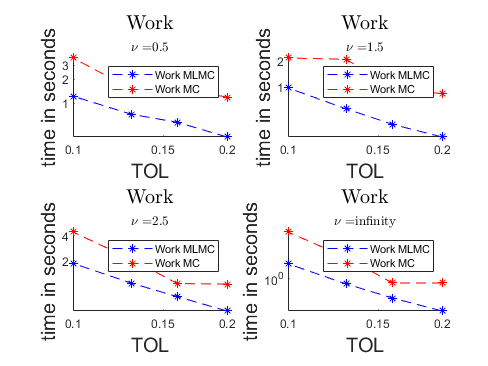

j = 1

MLMCres = -1.6001

MLMCvar = 0.0029

M_1 = 485

M_2 = 13

MLMCres = -1.5308

MLMCvar = 0.0016

M_1 = 758

M_2 = 20

MLMCres = -1.5941

MLMCvar = 0.0011

M_1 = 1149

M_2 = 31

MLMCres = -1.6135

MLMCvar = 7.5297e-04

M_1 = 1941

M_2 = 52

j = 2

MLMCres = -1.6902

MLMCvar = 0.0030

M_1 = 638

M_2 = 51

MLMCres = -1.6464

MLMCvar = 0.0024

M_1 = 997

M_2 = 79

MLMCres = -1.6411

MLMCvar = 0.0014

M_1 = 1510

M_2 = 120

MLMCres = -1.5943

MLMCvar = 7.0638e-04

M_1 = 2551

M_2 = 203

j = 3

MLMCres = -1.5635

MLMCvar = 0.0022

M_1 = 1138

M_2 = 438

MLMCres = -1.6438

MLMCvar = 0.0016

M_1 = 1778

M_2 = 684

MLMCres = -1.5994

MLMCvar = 9.9006e-04

M_1 = 2693

M_2 = 1036

MLMCres = -1.6090

MLMCvar = 6.2469e-04

M_1 = 4551

M_2 = 1751

j = 4

MLMCres = -1.6313

MLMCvar = 0.0027

M_1 = 1149

M_2 = 297

MLMCres = -1.5952

MLMCvar = 0.0025

M_1 = 1796

M_2 = 463

MLMCres = -1.6799

MLMCvar = 0.0014

M_1 = 2720

M_2 = 702

MLMCres = -1.6370

MLMCvar = 7.9142e-04

M_1 = 4597

M_2 = 1186

TOL = [0.2,0.16,0.13,0.1];
I0=4;
h0=1/I0;
M0 = 10;
S0 = 80;
work_MLMC = zeros(length(nu),length(TOL));
work_QMC = zeros(length(nu),length(TOL));
figure
for j = 1:length(nu)
    j
    for i = 1:length(TOL)
        tMLMC = tic;
        [MLMCres, MLMCvar, M_1, M_2] = MLMC(TOL(i), h_MC(j), h, Var_1(j,:), C_1, Var_2(j,:), C_2, nu(j),cutoff_fourier(j))
        work_MLMC(j,i) = toc(tMLMC);

        tQMC = tic;
        [~,~,~,~,~,~,~,~] = AdaptiveMC(M0,S0, p(j), c_alpha, TOL(i), I0, h0, nu(j),cutoff_fourier(j));
        work_QMC(j,i) = toc(tQMC);
    end
    subplot(2,2,j)
    hold on
    plot(TOL,work_MLMC(j,:),'*--b')
    plot(TOL,work_QMC(j,:),'*--r')
    hold off
    set(gca, 'YScale', 'log', 'XScale', 'log')
    title('Work',['$\nu = $' , titles{j}],'FontSize',15,'interpreter','latex')
    xlabel('TOL','FontSize',15)
    ylabel('time in seconds','FontSize',15)
    legend('Work MLMC','Work MC')
end

work_QMC

work_QMC =     1.1977    1.5581    1.5163    3.7199
    0.8512    0.9615    2.0784    2.1472
    1.0284    1.0443    2.0621    4.4680
    0.8694    0.8682    1.8305    3.8742


work_MLMC

work_MLMC =     0.3778    0.5783    0.7296    1.2314
    0.2754    0.3830    0.5718    0.9867
    0.4814    0.7216    1.0566    1.8458
    0.3817    0.5587    0.8433    1.5234


5.3:

I=100;
h = 1./I;
nu = 0.5;
Y = randn(1,I);
[EWsort,EVsort] = eigC(I,h,nu);
sigma=sqrt(2);
rho=0.1;
c_alpha=1.65;

mu=zeros(5,3);
k=[-5 -10 -20];
start=[[0 1 0 0 0];[-1 0 0 0 0];[-1 0 0 0 0]];
%start = [[1.77 0 1.56 0 -0.38]; [2.3 0 1.9 0 -0.58];  [2.97 0 2.44 0 -0.94]];

%mu = start';

lb = [];
ub = [];
A = [];
b = [];
Aeq = [];
beq = [];
c = [];

ws = warning('off','all');
for i=1:3
    fminimizer = @(x) standardNormal(x)*(-1);
    options = optimoptions('fmincon','Algorithm','interior-point'); % run interior-point algorithm
    mu(:,i)=fmincon(fminimizer,start(i,:),A,b,Aeq,beq,lb,ub,@(x) nzcon(rho,sigma,c_alpha,I,h,nu,x,k(i),EWsort,EVsort));
    CalculateQoIforIS(c_alpha, I, h,nu,5,mu(:,i),k(i),EWsort,EVsort)
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1

mu

mu =    -1.8962   -6.7715  -13.5180
   -0.0059    0.0600    0.1252
   -1.3809   -3.3594   -7.2901
   -0.1619   -0.3543   -0.7688
    0.4341    1.3798    3.0681


%{
%}
M0 = 10000;

MCIS1ref =normalMC(@(x) shiftedQOI(x,mu(:,1),rho,sigma,c_alpha, I, h,nu,5,k(1),EWsort,EVsort),M0);
MCIS2ref =normalMC(@(x) shiftedQOI(x,mu(:,2),rho,sigma,c_alpha, I, h,nu,5,k(2),EWsort,EVsort),M0);
MCIS3ref =normalMC(@(x) shiftedQOI(x,mu(:,3),rho,sigma,c_alpha, I, h,nu,5,k(3),EWsort,EVsort),M0);
MCref =normalMC(@(x) CalculateQoIforIS(c_alpha, I, h,nu,5,x,k(1),EWsort,EVsort),M0);





This part does the MC simulations

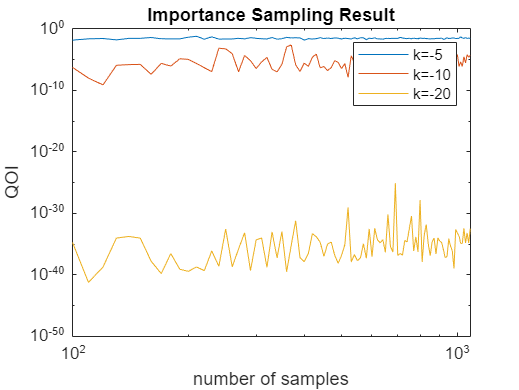

M0 = 100;
M=M0;
c_alpha = 1.65;
TOL=0.1;
MCIS=zeros(3,1000);
ac=1;
RE=ones(3,1);
rt=1;
MC=zeros(1,1000);
inc=10;
maxit=100;
minit=10;

[MCIS1 rt1 fvar1]=Adaptive(@(x) shiftedQOI(x,mu(:,1),rho,sigma,c_alpha, I, h,nu,5,k(1),EWsort,EVsort),TOL,M0,inc,MCIS1ref,minit,maxit);
minit=size(rt1,2)-1;
[MCIS2 rt2 fvar2]=Adaptive(@(x) shiftedQOI(x,mu(:,2),rho,sigma,c_alpha, I, h,nu,5,k(2),EWsort,EVsort),TOL,M0,inc,MCIS2ref,minit,maxit);
[MCIS3 rt3 fvar3]=Adaptive(@(x) shiftedQOI(x,mu(:,3),rho,sigma,c_alpha, I, h,nu,5,k(3),EWsort,EVsort),TOL,M0,inc,MCIS3ref,minit,maxit);
[MC rt fvar]=Adaptive(@(x) CalculateQoIforIS(c_alpha, I, h,nu,5,x,k(1),EWsort,EVsort),TOL,M0,inc,MCref,minit,maxit);

samples1=zeros(size(rt1,2)-1,1);
samples2=zeros(size(rt2,2)-1,1);
samples3=zeros(size(rt3,2)-1,1);
samples=zeros(size(rt,2)-1,1);
samples1(1)=M0;
samples2(1)=M0;
samples3(1)=M0;
samples(1)=M0;
for i=2:size(samples1,1)
    samples1(i)=samples1(i-1)+inc;
end
for i=2:size(samples2,1)
    samples2(i)=samples2(i-1)+inc;
end
for i=2:size(samples3,1)
     samples3(i)=samples3(i-1)+inc;
end
for i=2:size(samples,1)
     samples(i)=samples(i-1)+inc;
end

figure
loglog(samples1,MCIS1)
hold on
loglog(samples2,MCIS2)
loglog(samples3,MCIS3)
title('Importance Sampling Result')
legend('k=-5','k=-10','k=-20')
xlabel('number of samples')
ylabel('QOI')
hold off

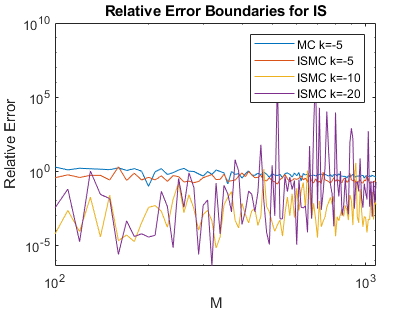




loglog(samples, rt(1,2:size(rt,2)))
hold on
loglog(samples1, rt1(1,2:size(rt1,2)))
loglog(samples2, rt2(1,2:size(rt2,2)))
loglog(samples3, rt3(1,2:size(rt3,2)))
title('Relative Error Boundaries for IS')
xlabel('M')
ylabel('Relative Error')
legend('MC k=-5','ISMC k=-5','ISMC k=-10', 'ISMC k=-20')
hold off

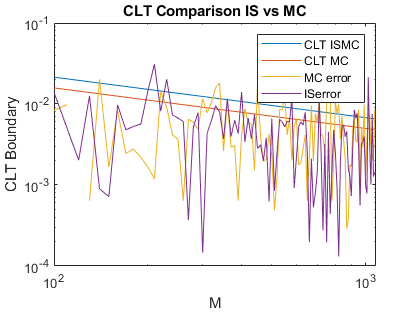


figure
finalMC=MC(1,size(rt,2)-1);
finalISMC=MCIS1(1,size(rt1,2)-1);
MCerror=abs(finalMC*ones(1,size(rt,2)-1)-MC(1,1:size(MC,2)));
ISerror=abs(finalISMC*ones(1,size(rt1,2)-1)-MCIS1(1,1:size(MCIS1,2)));
loglog(samples1,sqrt(fvar1)*c_alpha./sqrt(samples1));
hold on
loglog(samples,sqrt(fvar)*c_alpha./sqrt(samples));
loglog(samples,MCerror)
loglog(samples1,ISerror)
xlabel('M')
ylabel('CLT Boundary')
legend('CLT ISMC','CLT MC','MC error','ISerror')
title('CLT Comparison IS vs MC')
hold off

Functions:

function [stepsize,samples,MCRes,StatisticalEr,BiasEr,RE,Variance_level,rt] = AdaptiveMC(M0,S0, p,c_alpha, TOL, I0, h0,nu,cutoff)
    h=h0;
    rt=1;
    I=I0;
    MCRes=zeros(2,30);
    M=M0;
    S=S0;
    QDiff=zeros(1,30);

    y = i4_sobol_generate(cutoff,M,0);
    z = i4_sobol_generate(cutoff,M,0);
    Shift_y = cell(1,S);
    Shift_z = cell(1,S);
    for s = 1:S
        Shift_y{s} = rand(cutoff,M);
        Shift_z{s} = rand(cutoff,M);
    end
    Bias = 0;

    fourier = fourierkoeff(nu,cutoff);
    V1 = zeros(1,S);
    V2 = zeros(1,S);
    for s = 1:S
    y_shifted = applyShift(y,Shift_y{s});
    z_shifted = applyShift(z,Shift_z{s});
        for m=1:M
            V1(s) = V1(s) + CalculateQoIa2_3( I, h,fourier,cutoff,y_shifted(:,m),z_shifted(:,m));
            V2(s) = V2(s) + CalculateQoIa2_3( 2*I, h/2,fourier,cutoff,y_shifted(:,m),z_shifted(:,m));
        end
        V1=V1/M;
        V2=V2/M;
        MCRes(1,rt)=MCRes(1,rt)+V1(s);
        MCRes(2,rt)=MCRes(2,rt)+V2(s);
    
        Bias=Bias+V1(s)-V2(s);
    end
    QDiff(rt)=abs(Bias)/(M*S);
    Bias=QDiff(rt)/(1-0.5^p);
    MCRes(:,rt)=MCRes(:,rt)/(M*S);
    Var=0;
    for s=1:S
        Var=Var+(V1(s)-MCRes(1,rt))^2;
    end
    Var=Var/(S-1);
    Bias = abs(Bias/MCRes(2,rt));
    stat = sqrt(Var)*c_alpha/(sqrt(S)*abs(MCRes(2,rt)));
    RE=[Bias+stat];

    if Bias > 0.5*TOL
		h=h/2;
	    I=2*I;
    end
		
    if stat > 0.5*TOL
	    S=2*S;
    end

    Variance_level = [Var];
	BiasEr = [Bias];
	StatisticalEr = [stat];
    rt=rt+1;
    while ((Bias > 0.5*TOL) || (stat > 0.5*TOL))
        if rt == 30
            break
        end
        y = i4_sobol_generate(cutoff,M,0);
        z = i4_sobol_generate(cutoff,M,0);
        Shift_y = cell(1,S);
        Shift_z = cell(1,S);
        for s = 1:S
            Shift_y{s} = rand(cutoff,M);
            Shift_z{s} = rand(cutoff,M);
        end
        Bias = 0;
    
        fourier = fourierkoeff(nu,cutoff);
        V1 = zeros(1,S);
        V2 = zeros(1,S);
        for s = 1:S
        y_shifted = applyShift(y,Shift_y{s});
        z_shifted = applyShift(z,Shift_z{s});
            for m=1:M
                V1(s) = V1(s) + CalculateQoIa2_3( I, h,fourier,cutoff,y_shifted(:,m),z_shifted(:,m));
                V2(s) = V2(s) + CalculateQoIa2_3( 2*I, h/2,fourier,cutoff,y_shifted(:,m),z_shifted(:,m));
            end
            V1=V1/M;
            V2=V2/M;
            MCRes(1,rt)=MCRes(1,rt)+V1(s);
            MCRes(2,rt)=MCRes(2,rt)+V2(s);
        
            Bias=Bias+V1(s)-V2(s);
        end
        QDiff(rt)=abs(Bias)/(M*S);
        Bias=QDiff(rt)/(1-0.5^p);
        MCRes(:,rt)=MCRes(:,rt)/(M*S);
        Var=0;
        for s=1:S
            Var=Var+(V1(s)-MCRes(1,rt))^2;
        end
        Var=Var/(S-1);
        Bias = abs(Bias/MCRes(2,rt));
        stat = sqrt(Var)*c_alpha/(sqrt(S)*abs(MCRes(2,rt)));
        RE=[RE Bias+stat];
        Variance_level = [Variance_level Var];
		if Bias > 0.5*TOL
			BiasEr = [BiasEr Bias];
		    h=h/2;
			I=2*I;
        end
		if stat > 0.5*TOL
			StatisticalEr = [StatisticalEr stat];
			S=2*S;
        end
		rt=rt+1;
    end
    BiasEr = [BiasEr Bias];
    StatisticalEr = [StatisticalEr stat];
    Variance_level = [Variance_level Var];
    samples=zeros(length(StatisticalEr),1);
    samples(1)=S0;
    for m=2:length(StatisticalEr)
        samples(m)=samples(m-1)*2;
    end
	stepsize=zeros(length(BiasEr),1);
    stepsize(1)=h0;
    for m=2:length(BiasEr)
        stepsize(m)=stepsize(m-1)/2;
    end
end

function [MLMCres, MLMCvar, M1, M2] = MLMC(TOL, h_MC, h, Var_1, C_1, Var_2, C_2, nu,cutoff)
    for i = 1:length(h)
        if h(i) == h_MC
            index = i;
        end
    end
    
    M1 = round((TOL/3)^(-2) * sqrt( Var_1(index)/mean(C_1(:,index)) ) * ( sqrt(Var_1(index)*mean(C_1(:,index))) + sqrt(Var_1(index)*mean(C_1(:,index))) ) );
    M2 = round((TOL/3)^(-2) * sqrt( Var_2(index)/mean(C_2(:,index)) ) * ( sqrt(Var_1(index)*mean(C_1(:,index))) + sqrt(Var_2(index)*mean(C_2(:,index))) ) );
    
    S1 = 1;
    S2 = 1;

    h_use = h(index);
    I_use = 1/h_use;

    MCRes=zeros(2,1);
    y2 = i4_sobol_generate(cutoff,M2,0);
    z2 = i4_sobol_generate(cutoff,M2,0);

    y1 = i4_sobol_generate(cutoff,M1,0);
    z1 = i4_sobol_generate(cutoff,M1,0);

    V1 = zeros(1,S2);
    V2 = zeros(1,S2);
    V3 = zeros(1,S1);
    Shift_y1 = cell(1,S1);
    Shift_z1 = cell(1,S1);
    Shift_y2 = cell(1,S2);
    Shift_z2 = cell(1,S2);
    for s = 1:S1
        Shift_y1{s} = rand(cutoff,M1);
        Shift_z1{s} = rand(cutoff,M1);
    end
    for s = 1:S2
        Shift_y2{s} = rand(cutoff,M2);
        Shift_z2{s} = rand(cutoff,M2);
    end
 
    fourier = fourierkoeff(nu,cutoff);
    for s2 = 1:S2
        y2_shifted = applyShift(y,Shift_y2{s2});
        z2_shifted = applyShift(z,Shift_z2{s2});
        for m2=1:M2
            V1(s2) = V1(s2) + CalculateQoIa2_3( I_use, h_use,fourier,cutoff,y2_shifted(:,m2),z2_shifted(:,m2));
            V2(s2) = V2(s2) + CalculateQoIa2_3( 2*I_use, h_use/2,fourier,cutoff,y2_shifted(:,m2),z2_shifted(:,m2));
        end    
        MCRes(2,1) = MCRes(2,1) + V1(s2) - V2(s2);
        V1 = V1/M2;
        V2 = V2/M2;
    end
    for s1 = 1:S1
        for m1 = 1:M1
            V3(s1) = CalculateQoIa2_3( I_use, h_use,fourier,cutoff,y1_shifted(:,m1),z1_shifted(:,m1));
        end
        MCRes(1,1) = MCRes(1,1) + V3(s1);
        V3 = V3/M1;
    end
    MCRes(2,1) = MCRes(2,1)/(S2*M2);
    MCRes(1,1) = MCRes(1,1)/(S1*M1);
    Var=0;
    Var_diff = 0;
    for s2=1:S2
        Var_diff = Var_diff + ( V1(s2) - V2(s2) -MCRes(2,1))^2;
    end
    for s1 = 1:S1
        Var = Var + ( V3(s1) -MCRes(1,1) )^2;
    end
    MLMCres = MCRes(2,1) + MCRes(1,1);
    Var1 = Var/(S1-1);
    Var2 = Var_diff/(S2-1);    
    MLMCvar = Var1/S1 + Var2/S2;
end


function y =  assemble_F(I,h,f)
    y = zeros(I-1,1);
    for i = 1:I-1
        y(i) = f( i*h);
    end
end

function y = f(x)
    y = 4*pi^2*cos(2*pi*x);
end

function y = C(x,y,nu)
    if nu == 0.5
        y = 2 .* exp( - abs(x-y)/0.1 );
    end
    if nu == 1.5
        y = 2 .* (1 + sqrt(3)*abs(x-y)/0.1) .* exp( - sqrt(3)*abs(x-y)/0.1 );
    end
    if nu == 2.5
        y = 2 .* (1 + sqrt(5)*abs(x-y)/0.1 + sqrt(3)*abs(x-y).^2/0.1^2) .* exp( - sqrt(5)*abs(x-y)/0.1 );
    end
    if nu == 0 % for infinity
        y = 2 .* exp( - abs(x-y).^2/(2*0.1^2) );
    end
end

function f = fourierkoeff(nu,cutoff)
f = zeros(1,cutoff);
    for n = 1:cutoff
        f(n) = sqrt(integral( @(x) C(x,0,nu).* cos(n*pi*x/2) ,0,2));
    end
end

function [EWsort,EVsort] =  eigC(I,h,nu)
    sigma_a2 = sqrt(2);
    rho = 0.1;
    C_matrix = zeros(I,I);
        for m = 0:I-1
            for n = 0:I-1
                C_matrix(m+1,n+1) = C( ( m + 1/2)*h , ( n + 1/2)*h,nu);
            end
        end
        [EV,EW] = eig(h*C_matrix);
    
        for m = 1:I
            EV(:,m) = EV(:,m) ./ (sqrt(h)*norm(EV(:,m) )); %norming the EV
        end
        EVsort = zeros(I,I);
        for m = 1:I
            EVsort(:,m) = EV(:,I-m+1);
        end
        EWsort = zeros(I,I);
        for m = 1:I
            EWsort(m,m) = EW(I-m+1,I-m+1);
        end
end

function a = a2_2(x,I,Y,cutoff,EWsort,EVsort)
    h = 1/I;
    N = cutoff;
    if I < cutoff
        N=I;
    end
    
    j = 0; 
    while j*h < x %the input x is always a multiple of h, so j will be that factor
        j=j+1;
    end

    kappa = 0;
    for n = 1:N
           kappa = kappa + sqrt( EWsort(n,n) )*Y(n) * EVsort(j,n);
    end
    a = exp(kappa);

end

function a = a2_3(x,I,fourier,cutoff,y,z)
    N = cutoff;
    if I < cutoff
        N=I;
    end
   
    kappa = 0;
    for n = 1:N
           kappa = kappa + fourier(n)*( y(n)*cos(n*pi*x/2) + z(n)*sin(n*pi*x/2) );
    end
    a = exp(kappa);
end

function A = assemble_A(a,I,h,fourier,cutoff,y,z)% oder (a,I,h,Y,cutoff,EWsort,EVsort) für a2_2
    A = zeros(I-1,I-1);
    for i = 2:I-2
        x_right = (  (i-1)*h  +  i*h  )/2;
        x_left = ( (i-1)*h  + (i-2)*h )/2;
        a_left = a(x_left ,I,fourier,cutoff,y,z);
        a_right = a(x_right ,I,fourier,cutoff,y,z);
        A(i,i) = (a_left + a_right)/h^2;
        A(i,i+1) = -a_right/h^2;
        A(i,i-1) = -a_left/h^2;
    end
    a_start = a(h/2 ,I,fourier,cutoff,y,z);
    a_end = a( ((I-1)*h + I*h)/2 ,I,fourier,cutoff,y,z);
    a_left = a( ((I-1)*h + (I-2)*h)/2 ,I,fourier,cutoff,y,z);
    a_right = a(3*h/2 ,I,fourier,cutoff,y,z);
    A(1,1) = ( a_start + a_right )/h^2;
    A(I-1,I-1) = ( a_left  + a_end )/h^2;
    A(1,2) = -a_right/h^2 ;
    A(I-1,I-2) = -a_left/h^2;
end


function R = applyShift(R,S)
    R = R + S;
    R = mod(R,1);
    R = norminv(R);
end

function Q = CalculateQoI( I, h,Y,cutoff,EWsort,EVsort)
    F1 = assemble_F(I,h,@f);
    
    A = assemble_A(@a2_2,I,h,Y,cutoff,EWsort,EVsort);
    Q = h * sum(A\F1);
end

function Q = CalculateQoIa2_3( I, h,fourier,cutoff,y,z)
    F1 = assemble_F(I,h,@f);
    
    A = assemble_A(@a2_3,I,h,fourier,cutoff,y,z);
    Q = h * sum(A\F1);
end

function [Q] = CalculateQoIforIS(c_alpha, I, h,nu,cutoff,Y,K,EWsort,EVsort)
    F1 = assemble_F(I,h,@f);
    
    A = assemble_A(@a2_2,I,h,Y,cutoff,EWsort,EVsort);
    V1 = h * sum(A\F1);

    if (V1<K)
        Q=1;
    else
        Q=0;
    end
end

function [V1] = CalculateQoIforIS2(rho,sigma,c_alpha, I, h,nu,cutoff,Y,K,EWsort,EVsort)
    F1 = assemble_F(I,h,@f);
    
    A = assemble_A(@a2_2,I,h,Y,cutoff,EWsort,EVsort);
    V1 = h * sum(A\F1);
end

function [c,ceq] = nzcon(rho,sigma,c_alpha,I,h,nu,x,k,EWsort,EVsort)
    c = CalculateQoIforIS2(rho,sigma,c_alpha, I, h,nu,5,x,k,EWsort,EVsort)-k;
    ceq = [];
end

function res = normalMC(f,M)
    res=0;
    for i=1:M
        res=res+f(randn(1,5));
    end
    res=res/M;
end

function f= shiftedQOI(rv,shift,rho,sigma,c_alpha, I, h,nu,cutoff,k,EWsort,EVsort)
    sum=0;
    for i=1:cutoff
        sum=sum+(rv(i)+shift(i))^2-rv(i)^2;
    end
    f=CalculateQoIforIS(c_alpha, I, h,nu,cutoff,rv+shift,k,EWsort,EVsort)*exp(-0.5*sum);
end

function sng = standardNormal(y)
    sum=0;
    for i=1:size(y,2)
        sum=sum+y(i)^2;
    end
    sng=1/sqrt(2*pi)*exp(-0.5*sum);
end

function [res,rt, var] = Adaptive(f,tol,M0,inc,ref,minit,maxit)
    rt=1;
    M=M0;
    res=[];
    while((rt(size(rt,2))>tol | minit>size(rt,2)-1)&(size(rt,2)<maxit))
        temp=0;
        for i=1:M
            rv=randn(1,5);
            temp=temp+f(rv);
        end
        temp=temp/M;
        var=0;
        for i=1:M
            rv=randn(1,5);
            var=var+(temp-f(rv))^2;
        end
        var=var/M;
        rt=[rt sqrt(var)/sqrt(M)*1.65/ref];
        sqrt(var)/sqrt(M)*1.65/ref;
        M=M+inc;
        res=[res temp];
    end
end